# Working Directly in RGB Vector Space

    Dalam pemrosesan gambar berwarna, ada kasus di mana proses yang didasarkan pada individual color planes tidak setara dengan pemrosesan di RGB vector space. Pemrosesan vektor dalam pemrosesan gambar berwarna dapat dibagi menjadi 2 aplikasi, yaitu deteksi tepi warna (color edge detection) dan segmentasi wilayah (region segmentation).

## Membaca Gambar

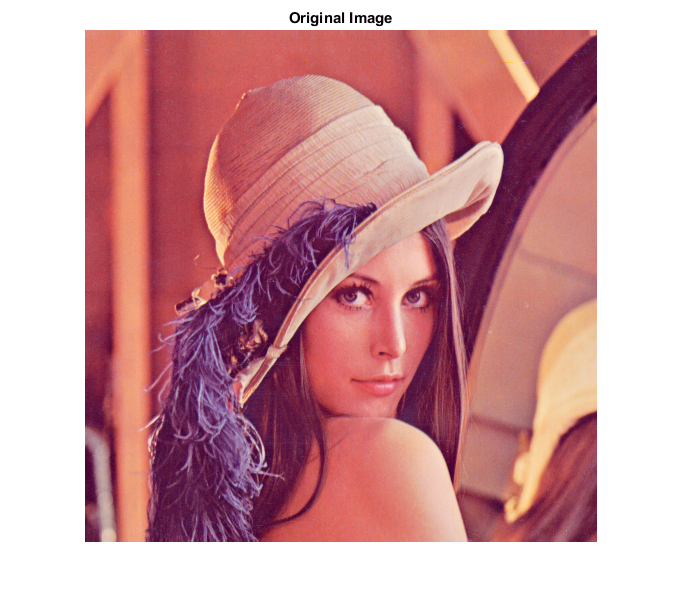

I = imread('./Input/Lena.tif');
imshow(I);
title('Original Image');

## Edge Detection

- Vertical Edges

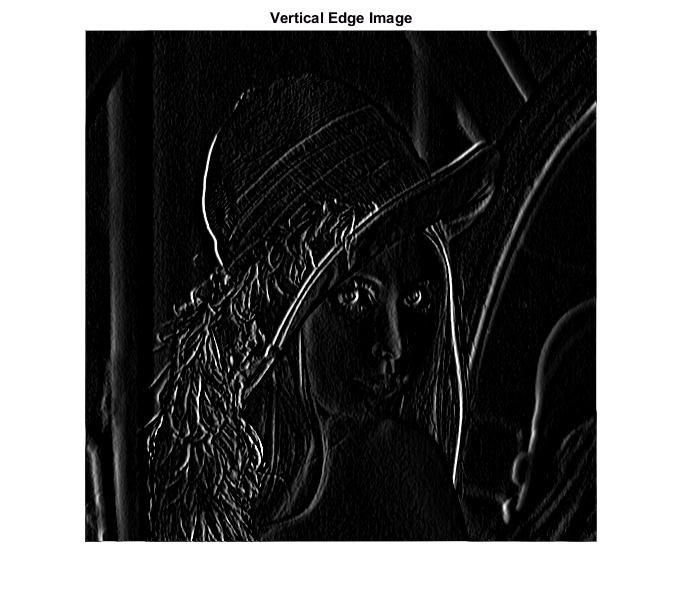

IVerEdge = double(rgb2gray(I));
IVerEdgeCopy = IVerEdge;
mask=[1, 0, -1;1, 0, -1;1, 0, -1];
  
% Putar citra 180 derajat dengan cara membalikkan citra ke atas ke bawah lalu dari kiri ke kanan
mask=flipud(mask); 
mask=fliplr(mask);

for i=2:size(IVerEdge, 1)-1
    for j=2:size(IVerEdge, 2)-1
  
        % mengalikan nilai mask dengan nilai piksel gambar yang sesuai
        neighbourMatrix=mask.*IVerEdgeCopy(i-1:i+1, j-1:j+1); 
        avgValue=sum(neighbourMatrix(:));
        IVerEdge(i, j)=avgValue;
    end
end

imwrite(IVerEdge, '.\Output\Lena_veredge.tif');
imshow(uint8(IVerEdge));
title('Vertical Edge Image');

- Horizontal Edges

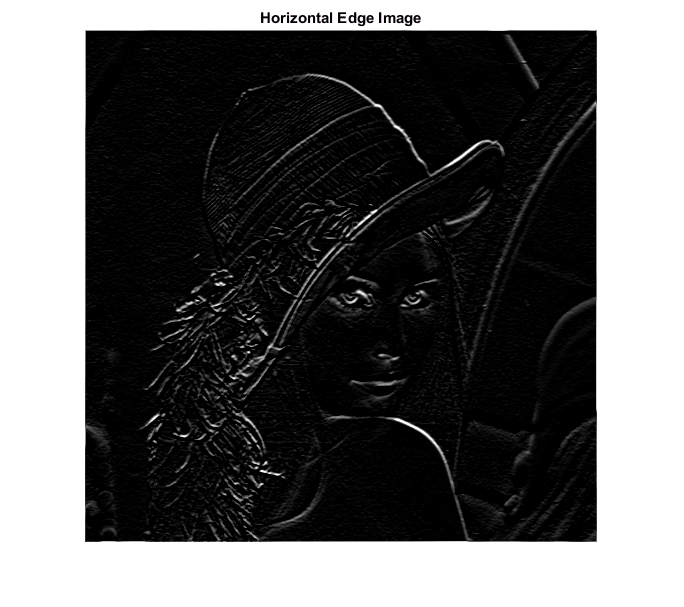

IHorEdge = double(rgb2gray(I));
IHorEdgeCopy = IHorEdge;
mask=[1, 1, 1;0, 0, 0;-1, -1, -1];
  
% Putar citra 180 derajat dengan cara membalikkan citra ke atas ke bawah lalu dari kiri ke kanan
mask=flipud(mask); 
mask=fliplr(mask);

for i=2:size(IHorEdge, 1)-1
    for j=2:size(IHorEdge, 2)-1
  
        % mengalikan nilai mask dengan nilai piksel gambar yang sesuai
        neighbourMatrix=mask.*IHorEdgeCopy(i-1:i+1, j-1:j+1); 
        avgValue=sum(neighbourMatrix(:));
        IHorEdge(i, j)=avgValue;
    end
end

imwrite(IHorEdge, '.\Output\Lena_horedge.tif');
imshow(uint8(IHorEdge));
title('Horizontal Edge Image');

## Perbandingan

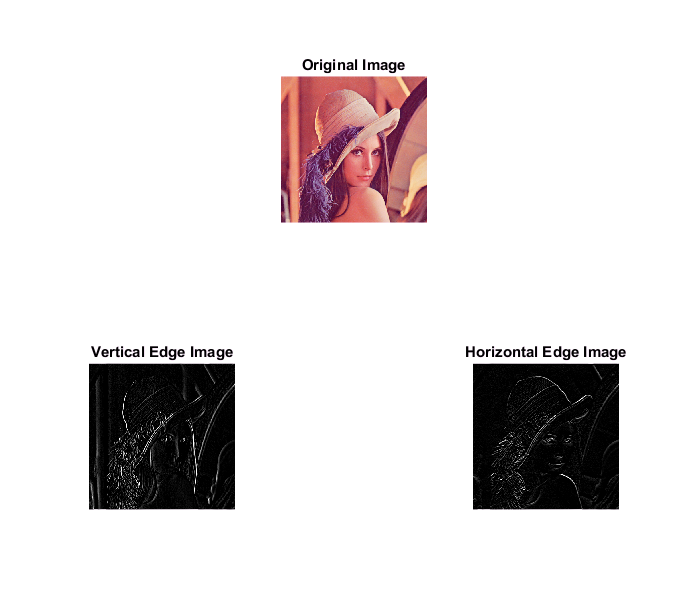

subplot(2,3,2); imshow(I);
title('Original Image');
subplot(2,3,4); imshow(uint8(IVerEdge));
title('Vertical Edge Image');
subplot(2,3,6); imshow(uint8(IHorEdge));
title('Horizontal Edge Image');